% example splines

%NOTE: In the slide is not used time normalization contrary to the example

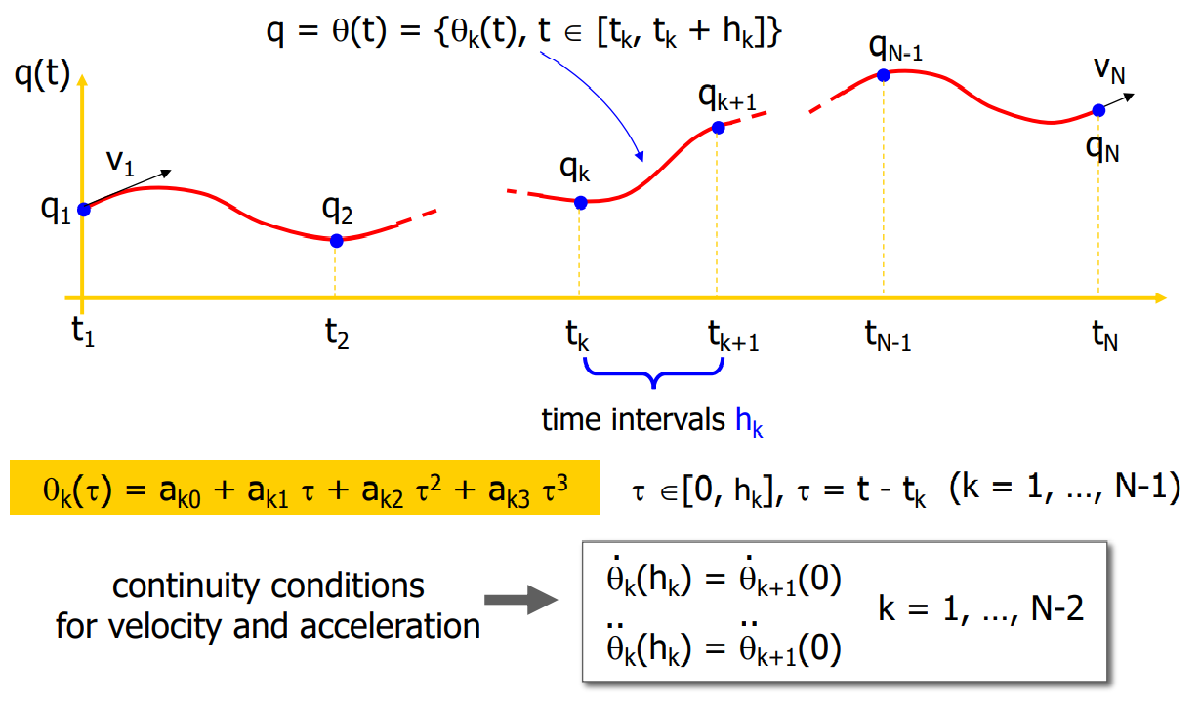

tvals = [1 2 2.5 4];
qvals = [45 90 -45 45];

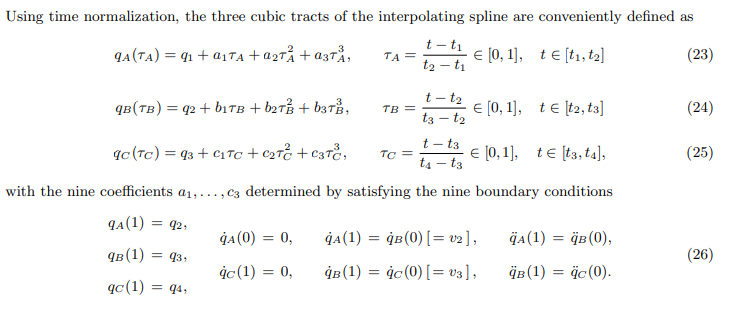

    % If initial and final velocities need to be imposed,
    % this needs modifications (slide 13).

    % tau = t - t1 --> tau = (t - t1) / h

    if exist('norm', 'var')
        normalize = norm;
    else
        normalize = 1;
    end


    %% Calcs
    N = size(tvals, 2);
    t = sym ('t', [1, N], 'real');
    q = sym ('q', [1, N], 'real');
    v = sym ('v', [1, N], 'real');

    if ~exist('v1', 'var')
        v1 = 0;
        vn = 0;
    end

    v(1) = v1;
    v(N) = vn;

    h = t(2:N) - t(1:N-1)

$$h = \left(\begin{array}{ccc} t_{2}-t_{1} & t_{3}-t_{2} & t_{4}-t_{3} \end{array}\right)$$

    fprintf('_________________________________________________________________\n');

_________________________________________________________________


    fprintf('First at all, we write the coefficients as function of velocities\n\n');

First at all, we write the coefficients as function of velocities



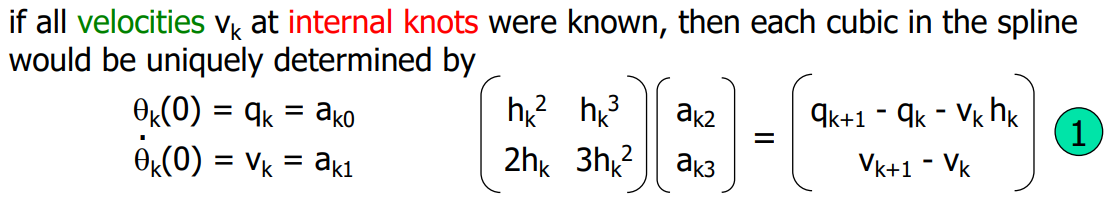

    for i = 1:N-1
        fprintf('Symbolic Cubic %d parameters:\n', i);

        a0 = q(i);
        if normalize == 81
            a1 = v(i) * h(i);
            a = inv([1, 1; 2/h(i), 3/h(i)]) * [q(i+1) - q(i) - v(i) * h(i); v(i+1) - v(i)];
        else
            a1 = v(i);
            a = inv([h(i)^2, h(i)^3; 2*h(i), 3*h(i)^2]) * [q(i+1) - q(i) - v(i) * h(i); v(i+1) - v(i)];
        end

        % For normalization use this one:
        a = simplify([a0; a1; a])
    end

Symbolic Cubic 1 parameters:


$$a = \left(\begin{array}{c} q_{1}\\ 0\\ -\frac{3\,q_{1}-3\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}}{{\left(t_{1}-t_{2}\right)}^{2}}\\ -\frac{2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}}{{\left(t_{1}-t_{2}\right)}^{3}} \end{array}\right)$$

Symbolic Cubic 2 parameters:


$$a = \left(\begin{array}{c} q_{2}\\ v_{2}\\ -\frac{3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3}}{{\left(t_{2}-t_{3}\right)}^{2}}\\ -\frac{2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3}}{{\left(t_{2}-t_{3}\right)}^{3}} \end{array}\right)$$

Symbolic Cubic 3 parameters:


$$a = \left(\begin{array}{c} q_{3}\\ v_{3}\\ -\frac{3\,q_{3}-3\,q_{4}-2\,t_{3}\,v_{3}+2\,t_{4}\,v_{3}}{{\left(t_{3}-t_{4}\right)}^{2}}\\ -\frac{2\,q_{3}-2\,q_{4}-t_{3}\,v_{3}+t_{4}\,v_{3}}{{\left(t_{3}-t_{4}\right)}^{3}} \end{array}\right)$$

    fprintf('__________________________******_____________________________\n');

__________________________******_____________________________


    fprintf('_________________________________________________________________\n');

_________________________________________________________________


    fprintf('To impose continuity of the acceleration at the internal knots\n\n');

To impose continuity of the acceleration at the internal knots



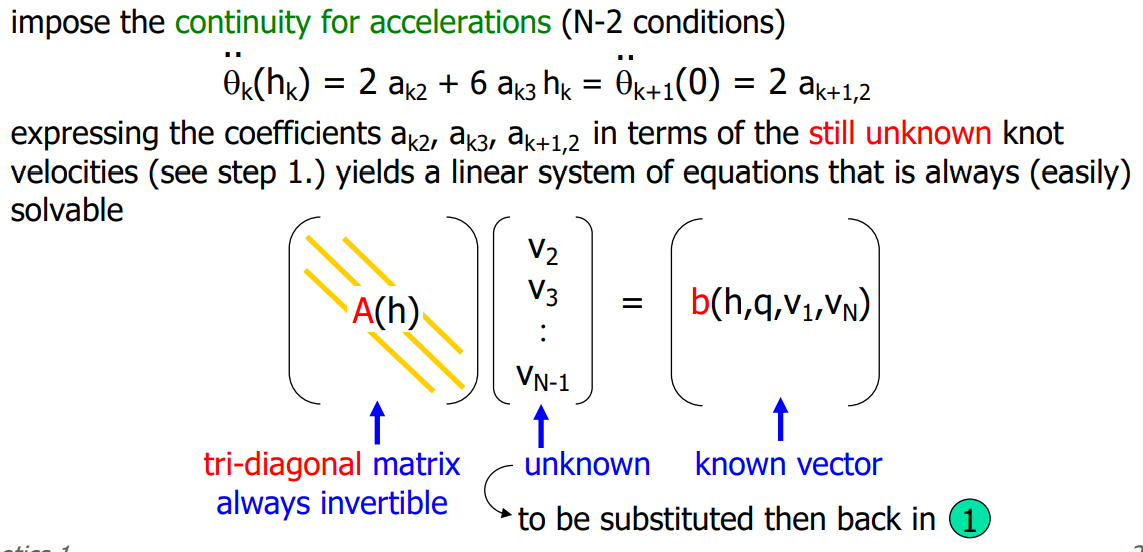


    % A is a N-2 x N-2 matrix
    % The same for all joints
    A = sym(zeros([N-2, N-2]));
    for i = 1:N-2
        if i-1 > 0
            A(i-1, i) = h(i-1);
        end
        A(i, i) = 2 * (h(i) + h(i+1));
        if i+1 <= N-2
            A(i+1, i) = h(i+2);
        end
    end

    % b changes for each joint
    % as it depends on q
    b = sym(zeros([N-2, 1]));
    for i = 1:N-2
        b(i) = 3 * (q(i+2) - q(i+1)) * h(i)/h(i+1) + 3 * (q(i+1) - q(i)) * h(i+1)/h(i);
    end
    b = b - [h(2) * v1; zeros([N-4,1]); h(N-2) * vn];

    A, b %a(h), b(...)

$$A = \left(\begin{array}{cc} 2\,t_{3}-2\,t_{1} & t_{2}-t_{1}\\ t_{4}-t_{3} & 2\,t_{4}-2\,t_{2} \end{array}\right)$$

$$b = \left(\begin{array}{c} -\frac{\left(3\,q_{1}-3\,q_{2}\right)\,\left(t_{2}-t_{3}\right)}{t_{1}-t_{2}}-\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{1}-t_{2}\right)}{t_{2}-t_{3}}\\ -\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{3}-t_{4}\right)}{t_{2}-t_{3}}-\frac{\left(3\,q_{3}-3\,q_{4}\right)\,\left(t_{2}-t_{3}\right)}{t_{3}-t_{4}} \end{array}\right)$$

    
    fprintf('__________________________******_____________________________\n');

__________________________******_____________________________



    %% Numberical Results
    % Convert everything to numerical values
    A = subs(A, t, tvals);
    b = subs(b, t, tvals);
    b = subs(b, q, qvals);
    h = subs(h, t, tvals);

    v1 = subs(v1, q, qvals);
    v1 = subs(v1, t, tvals);
    vn = subs(vn, q, qvals);
    vn = subs(vn, t, tvals);

double(inv(A))

ans =     0.3810   -0.0952
   -0.1429    0.2857


    v = inv(A) * b; % [v2 ... v_N-1]
    v = eval([v1; v; vn])

v =          0
 -175.7143
 -215.3571
         0


    coeffs = [];
    for i = 1:N-1
        % fprintf('Numeric Cubic %d parameters:\n', i);
        a0 = qvals(i);
        
        if normalize == 18
            fprintf("cidiid");
            a1 = v(i) * h(i);
            a = inv([1, 1; 2/h(i), 3/h(i)]) * [qvals(i+1) - qvals(i) - v(i) * h(i); v(i+1) - v(i)];
        else
            a1 = v(i);
            a = inv([h(i)^2, h(i)^3; 2*h(i), 3*h(i)^2]) * [qvals(i+1) - qvals(i) - v(i) * h(i); v(i+1) - v(i)];
        end
        a = eval([a0, a1, a']);

        coeffs = [coeffs; a];
    end

coeffs

coeffs =    45.0000         0  310.7143 -265.7143
   90.0000 -175.7143 -486.4286  595.7143
  -45.0000 -215.3571  407.1429 -149.0476


    fprintf('_________________________________________________________________\n');

_________________________________________________________________


    fprintf('Results\n\n');

Results



    for i=1:size(v,1)
        fprintf('v%d = %f \n',i, v(i)); 
    end

v1 = 0.000000 
v2 = -175.714286 
v3 = -215.357143 
v4 = 0.000000 


    for i=1:size(coeffs, 1)
        fprintf('Symbolic Cubic %d parameters:\n', i);
        for j=1:size(coeffs,2)
            fprintf('a%d = %f \n',j-1, coeffs(i,j)); 
        end
    end

Symbolic Cubic 1 parameters:


a0 = 45.000000 
a1 = 0.000000 
a2 = 310.714286 
a3 = -265.714286 


Symbolic Cubic 2 parameters:


a0 = 90.000000 
a1 = -175.714286 
a2 = -486.428571 
a3 = 595.714286 


Symbolic Cubic 3 parameters:


a0 = -45.000000 
a1 = -215.357143 
a2 = 407.142857 
a3 = -149.047619 


    
    fprintf('__________________________******_____________________________\n');

__________________________******_____________________________


    % Test using directly the function
    %   function [coeffs, v] = splines(tvals, qvals, v1, vn, norm)

    tvals = [1 2 2.5 4];
    qvals = [45 90 -45 45];

    [cofs, vels] = splines(tvals, qvals);

$$A = \left(\begin{array}{cc} 2\,t_{3}-2\,t_{1} & t_{2}-t_{1}\\ t_{4}-t_{3} & 2\,t_{4}-2\,t_{2} \end{array}\right)$$

$$b = \left(\begin{array}{c} -\frac{\left(3\,q_{1}-3\,q_{2}\right)\,\left(t_{2}-t_{3}\right)}{t_{1}-t_{2}}-\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{1}-t_{2}\right)}{t_{2}-t_{3}}\\ -\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{3}-t_{4}\right)}{t_{2}-t_{3}}-\frac{\left(3\,q_{3}-3\,q_{4}\right)\,\left(t_{2}-t_{3}\right)}{t_{3}-t_{4}} \end{array}\right)$$

Symbolic Cubic 1 parameters:


$$a = \left(\begin{array}{c} q_{1}\\ 0\\ 3\,q_{2}-3\,q_{1}+v_{2}\,\left(t_{1}-t_{2}\right)\\ 2\,q_{1}-2\,q_{2}-v_{2}\,\left(t_{1}-t_{2}\right) \end{array}\right)$$

Symbolic Cubic 2 parameters:


$$a = \left(\begin{array}{c} q_{2}\\ -v_{2}\,\left(t_{2}-t_{3}\right)\\ 3\,q_{3}-3\,q_{2}+3\,v_{2}\,\left(t_{2}-t_{3}\right)-\left(t_{2}-t_{3}\right)\,\left(v_{2}-v_{3}\right)\\ 2\,q_{2}-2\,q_{3}-2\,v_{2}\,\left(t_{2}-t_{3}\right)+\left(t_{2}-t_{3}\right)\,\left(v_{2}-v_{3}\right) \end{array}\right)$$

Symbolic Cubic 3 parameters:


$$a = \left(\begin{array}{c} q_{3}\\ -v_{3}\,\left(t_{3}-t_{4}\right)\\ 3\,q_{4}-3\,q_{3}+2\,v_{3}\,\left(t_{3}-t_{4}\right)\\ 2\,q_{3}-2\,q_{4}-v_{3}\,\left(t_{3}-t_{4}\right) \end{array}\right)$$

    
    fprintf('_________________________________________________________________\n');

_________________________________________________________________


    fprintf('Results\n\n');

Results



    for i=1:size(vels,1)
        fprintf('v%d = %f \n',i, vels(i)); 
    end

v1 = 0.000000 
v2 = -175.714286 
v3 = -215.357143 
v4 = 0.000000 


    for i=1:size(cofs, 1)
        fprintf('Symbolic Cubic %d parameters:\n', i);
        for j=1:size(cofs,2)
            fprintf('a%d = %f \n',j-1, cofs(i,j)); 
        end
    end

Symbolic Cubic 1 parameters:


a0 = 45.000000 
a1 = 0.000000 
a2 = 310.714286 
a3 = -265.714286 


Symbolic Cubic 2 parameters:


a0 = 90.000000 
a1 = -87.857143 
a2 = -121.607143 
a3 = 74.464286 


Symbolic Cubic 3 parameters:


a0 = -45.000000 
a1 = -323.035714 
a2 = 916.071429 
a3 = -503.035714 


    
    fprintf('__________________________******_____________________________\n');

__________________________******_____________________________


cofs

cofs =    45.0000         0  310.7143 -265.7143
   90.0000  -87.8571 -121.6071   74.4643
  -45.0000 -323.0357  916.0714 -503.0357


% test spline_plot

N = 4

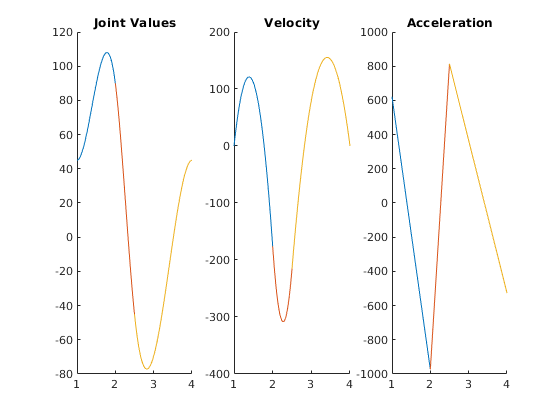

spline_plot(tvals, cofs)